%% Simulation of linear system of monocopter with flaps
J = 3.2284E-6; % moment of inertia of the rotor
b = 3.5077E-6; % motor viscous friction constant 
K = 0.0274; % electromotive force constant, motor torque constant 
R = 4; % electric resistance 
L = 2.75E-6; % electric inductance  
s = tf('s');
servo = K/(s*((J*s+b)*(L*s+R)+K^2)); % includes the integral to positional angle alrd
H_servo = 1;
H_omega_dot_tf = 1; % lpf is needed and tuned here for indi, ndi is better only  
stf = servo/(1+(servo*H_servo));
%isstable(stf)
%pole(stf)
%omega_dot_tf = stf; % ndi
omega_dot_tf = stf/(1+(stf*H_omega_dot_tf)); % indi
% isstable(omega_dot_tf)
% pole(omega_dot_tf)
%sys = feedback(stf,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)

% to simulate step input of a single servo angle
% t = 0:0.001:0.3;
% Config = RespConfig('Amplitude',5);
% step(omega_dot_tf, t, Config) % step function here is in the form of a servo angle 
% ylabel('Position, \theta (radians)')
% title('Response to a Step Reference')
%legend('Kp = 1',  'Kp = 11',  'Kp = 21')

%% to simulate disturbance step input
Jxx = 0.00099;
Jzz = 0.001;
% disturbance_torque_tf = ((1/J)*(1-(H_omega_dot_tf*omega_dot_tf)));
% t = 0:0.001:0.2;
% Config = RespConfig('Amplitude',5);
% step(disturbance_torque_tf, t, Config) % step function here is in the form of a servo angle 
% ylabel('omega_dot_tf')
% title('Response to a Step Disturbance')

%% to simulate step input to isolate precession portion and vertical rotation rate
% hz = 5.6;
% rps = hz * 2 * pi * -1;
% H_precession = Jxx/(Jzz*-22) % dampener, precession inner loop
H_precession = 0;
precession_tf = omega_dot_tf/(1-(omega_dot_tf*H_precession)); % indi
% t = 0:0.001:0.3;
% Config = RespConfig('Amplitude',5);
% step(precession_tf, t, Config) % step function here is in the form of a servo angle 
% ylabel('radians/seconds')
% title('Response to a Step Reference')

%% find the lift force to hold alt 
g = 9.81;
cd = 0.093; %0.023;
rho = 1.225;
radius = 0.61;
pitch = 41;
pitch = abs(pitch);
mass = 0.16;
cd = cd * pitch; % gradient for cd taken from naca 0006, pitch must be in deg
chord_length = 0.1;
omega_z_body = -22; % the lower the btr apparently
rps = omega_z_body;
drag_rotation = 1*(cd*(omega_z_body^2)*rho*chord_length*(radius^3))/(6*mass);
com = 1/(-(g + drag_rotation));
%com = -1;

H_q = 1;
H_omega = 1;
H_a = 1;

kp_omega = 1100; % input 2 is jerk control 
kp_q = 850; % input 3 quartenion control
D = 3; % input 2 is jerk control
snap_coeff = 1;
% input 1 is snap control 


% conclusion: maybe the single motor vs w flap wud help  

% numerator = precession_tf*Jzz*rps*com*((s^2)+(s*kp_omega)+(D*kp_omega)+kp_q);
numerator = [(snap_coeff*precession_tf*Jzz*rps*com),precession_tf*Jzz*rps*com*kp_omega,precession_tf*Jzz*rps*com*((D*kp_omega)+kp_q)];
% denominator = (com((s^2)*((Jzz*rps)+(Jxx*precession_tf*H_disturbance_p))+(s*H_omega*precession_tf*kp_omega*Jzz*rps)+(precession_tf*kp_q*Jzz*rps*H_q))+(Jzz*rps*H_a*precession_tf));
% denominator = [-1*com*Jxx*precession_tf*H_a,Jzz*rps,H_omega*precession_tf*kp_omega*Jzz*rps,(com*precession_tf*kp_q*Jzz*rps*H_q) + (Jzz*rps*H_a*precession_tf)]
denominator = [com*Jzz*rps,com*H_omega*precession_tf*kp_omega*Jzz*rps,(com*precession_tf*kp_q*Jzz*rps*H_q) + (Jzz*rps*H_a*precession_tf)]

denominator =
 
  From input 1 to output:
  0.0003478
 
  From input 2 to output:
                            7.335e-36 s^9 + 3.201e-29 s^8 + 4.656e-23 s^7 + 2.258e-17 s^6 + 4.011e-15 s^5 + 2.854e-13 s^4 + 1.036e-11 s^3 + 1.68e-10 s^2
  --------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  6.213e-45 s^12 + 3.615e-38 s^11 + 7.887e-32 s^10 + 7.648e-26 s^9 + 2.782e-20 s^8 + 6.589e-18 s^7 + 7.623e-16 s^6 + 5.456e-14 s^5 + 2.455e-12 s^4 + 6.643e-11 s^3 + 8.782e-10 s^2
 
  From input 3 to output:
                          3.259e-80 s^21 + 3.318e-73 s^20 + 1.448e-66 s^19 + 3.511e-60 s^18 + 5.107e-54 s^17 + 4.457e-48 s^16 + 2.162e-42 s^15 + 4.497e-37 s^14 + 1.862e-34 s^13 + 3.689e-32 s^12 + 4.619e-30 s^11 + 4.039e-28 s^10 + 2.569e-26 s^9 + 1.202e-24 s^8 + 4.083e-23 s^7 + 9.665e-22 s^6 + 1.449e-20 s^5 + 1.055e-19 s^4
  -----------------------------------------------------

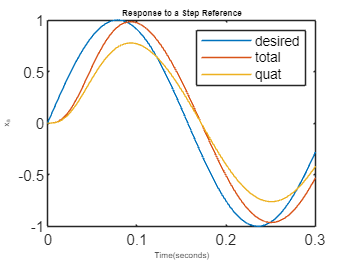

a_tf = tf(numerator,denominator);


t = 0:0.001:0.3;
u = sin(20*t);
Config = RespConfig('Amplitude',10);
all_inputs = step(a_tf, t, Config); % step function here is in the form of a servo angle 
% ylabel('x_a','FontSize',5)
% xlabel('Time(seconds)','FontSize',5)
% title('Response to a Step Reference','FontSize',5)

% isstable(a_tf)
% pole(a_tf)
% snap = all_inputs(:,:,1);
% jerk = all_inputs(:,:,2);
% quat = all_inputs(:,:,3);

snap = lsim(a_tf(1,1),u,t);
jerk = lsim(a_tf(1,2),u,t);
quat = lsim(a_tf(1,3),u,t);

total = snap + jerk + quat;
plot (t,u)
hold on
plot(t,total)
plot(t,quat)
hold off


ylabel('x_a','FontSize',5)
xlabel('Time(seconds)','FontSize',5)
title('Response to a Step Reference','FontSize',5)
legend('desired','total','quat')